# MATLAB Assignment 1 - Filter/Effect

Author: Kevin Horta

## Introduction

This assigment / script is to apply the gray scale filter to a image and then erode and dilate it with image processing meathods in a MATLAB live script.

## Reading Image

Read the Image into MATLAB with the imread() function. We find the image we desire with the uigetfile() function and assign it to Filename 

Filename = uigetfile(".jpg")

Filename = 'IMG1.jpg'

IMG = imread(Filename);

## Displaying Image

Display the Image we loading into MATLAB with imshow() function

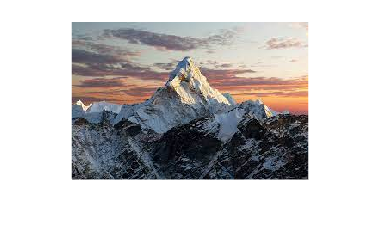

imshow(IMG)

## Applying Filter

Here we apply the gray filter to the image that converts the image pixel values from a RGB to just a single value of brightness in each pixel

IMG_G = im2gray(IMG);

## Applying Effect

Here we create a structuring element of a square with a size of 4x4 and then utilize it for opening the image which is erode and dilate done by MATLAB then we display it with imshow()

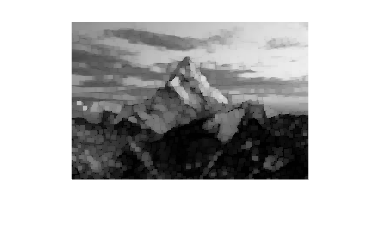

structure = strel("square", 4);

IMG_G_E = imopen(IMG_G,structure);

imshow(IMG_G_E);

## Saving PNG Image

Here we write the image and save it has a PNG or JPG depending of our choice of file type into our directory of the file named NEWIMAGE1

The way we give the user a choice is using the function listdlg, assigning a value to selectedFormat of 1 or 2 then retreiving what file type to name it with fileFormats having the actual type to add to NEWIMAGE1

fileFormats = {'png', 'jpg'};
[selectedFormat, ~] = listdlg("PromptString","Select file type","SelectionMode","single","ListString",{'png', 'jpg'});

imwrite(IMG_G_E, ['NEWIMAGE1.' fileFormats{selectedFormat}])
